# **디지털신호처리 ****HW#1**

Due date : 2021.10.21. 23:59

**이름**** : 김강건**

**학번**** : 201910510**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : https://github.com/GangGeon10/DSP_homework.git**

1. 다음 신호를 stem 함수를 이용하여 그려라.

1) 


n = [-200:200];

x = 5*(cos(0.49*pi*n) + cos(0.51*pi*n));
subplot(2,1,1);
stem(n,x);
xlabel('n'); ylabel('x(n)');



2) 

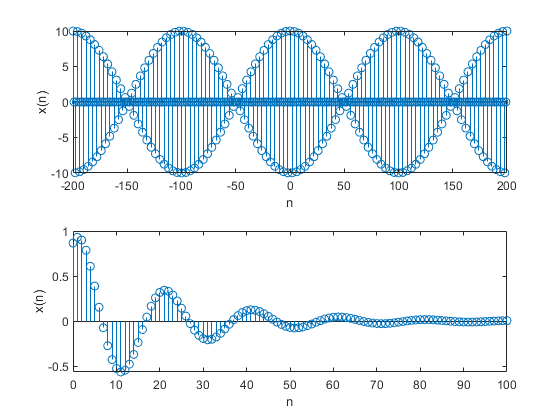


n = [0:100];

x = (exp(-0.05 * n) ) .* sin(0.1*pi*n + pi/3);
subplot(2,1,2);
stem(n,x);
xlabel('n'); ylabel('x(n)');

2.  (P2.16) LTI 시스템의 차분 방정식이 다음과 같다.


$$y\left(n\right)-0\ldotp 5y\left(n-1\right)+0\ldotp 25y\left(n-2\right)=x\left(n\right)+2x\left(n-1\right)+x\left(n-3\right)$$


1) MATLAB의 impz 함수를 사용하여 0<=n<=100 구간에서 시스템의 임펄스 응답을 구하고 stem을 이용해서 그려라.

b = [1 2 0 1];
a = [1 -0.5 0.25];
n = [0:100];

h = impz(b,a,n);
subplot(2,1,1);
stem(n,h);
xlabel('n'); ylabel('h(n)'); 
title('Impulse Response');


2) 이 임펄스 응답으로부터 안정성을 판별하라. (sum, abs 함수 사용)


sum(abs(h))

ans = 5.8571

3) 만약 이 시스템의 입력이 

x(n)= [5 + 3cos(0.2*pi*n) + 4sin(0.6*pi*n)]u(n) 이면,

 filter 함수를 사용하여0<=n<=200 구간에서 응답 y(n)을 구하라.

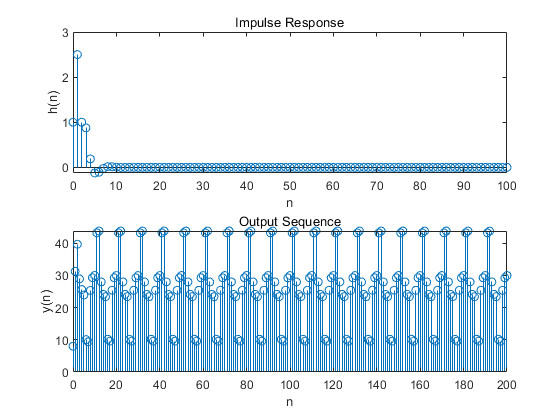

b = [1 2 0 1];
a = [1 -0.5 0.25];
n = [0:200];

x = 5 +3*cos(0.2*pi*n) + 4*sin(0.6*pi *n);

y = filter(b,a,x);

subplot(2,1,2);
stem(n,y);
xlabel('n'); ylabel('y(n)');
title('Output Sequence');

3. (P2.20) 

일 때, 다음을 그려라. 

1) y(n)의 처음 51개 샘플을 stem 함수 이용해서 그려라. 


k = [0:50];
n = [0:50];
x = (0.8).^n;
h1 = (-0.9).^(n-k);

y =x.*h1;

subplot(1,3,1);
stem(n,y);
xlabel('n'); ylabel('y(n)');
title('y(n)');


2) x(n)과 h(n)을 26개의 샘플이 되도록 자른뒤, conv 함수를 이용해서 y(n)을 구하고 stem 이용해서 그려라. 

n = [0:25];
x = (0.8).^n;
h = (-0.9).^n;
y = conv(h,x);

subplot(1,3,2);
N = [0:50];
stem(N,y);
xlabel('n'); ylabel('y(n)');
title('y(n)');


3) filter 함수를 이용해서 $x\left(n\right)\ast h\left(n\right)$의 처음 51개 샘플을 구하고 stem 이용해서 그려라. 

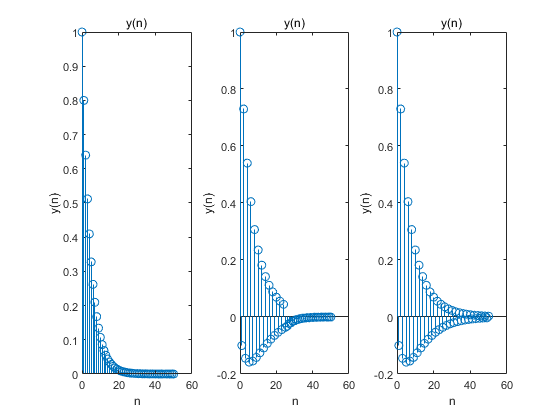

b = [1];
a = [1 0.9];
n = [0:50];

x = ((0.8).^n);
y = filter(b,a,x);
subplot(1,3,3); 
stem(n,y);
xlabel('n'); ylabel('y(n)');
title('y(n)');

4. (P3.14) 임펄스 응답으로 기술된 각 선형 시불변 시스템에 대해 구간 $\left\lbrack -\pi ,\pi \right\rbrack$에서 주파수 응답 함수 $H\left(e^{j\omega } \right)$을 구하고 크기 응답과 위상 응답을 그려라. 

1) $h\left(n\right)={\left(0\ldotp 9\right)}^{|n|}$


w = [0:1:500]*pi/500;

H = 2*exp(j*w) ./ (exp(j*w)-0.9*ones(1,501));
magH = abs(H);
angH = angle(H);
subplot(2,2,1); plot(w/pi, magH); 
xlabel('frequency in pi units'); ylabel('|H|'); grid;
title('Magnitude Response');
subplot(2,2,2); plot(w/pi, angH/pi);
xlabel('frequency in pi units'); ylabel('Phase in pi Radians'); grid;
title('Phase Response');

2) $h\left(n\right)=\left\lbrack {\left(0\ldotp 5\right)}^n +{\left(0\ldotp 4\right)}^n \right\rbrack u\left(n\right)$

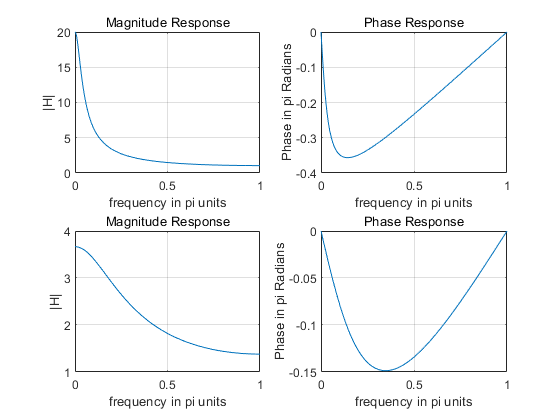


w = [0:1:500]*pi/500;

H1 = exp(j*w) ./ (exp(j*w)- 0.5*ones(1,501));
H2 = exp(j*w) ./ (exp(j*w)- 0.4*ones(1,501));

H = H1 + H2;
magH = abs(H);
angH = angle(H);
subplot(2,2,3); plot(w/pi, magH);
xlabel('frequency in pi units'); ylabel('|H|'); grid;
title('Magnitude Response');
subplot(2,2,4); plot(w/pi, angH/pi);
xlabel('frequency in pi units'); ylabel('Phase in pi Radians'); grid;
title('Phase Response');

5. (P3.17) 

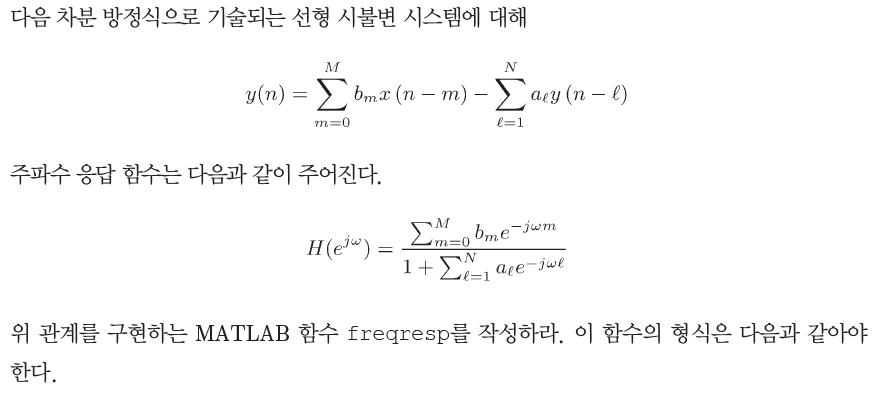

%
%function [H] = freqresp(b,a,w)
% H = frequency response array evaluated at w frequencies
% b = numerator coefficient array
% a = denominator coefficient array (a(1) = 1)
% w = frequency location array

%end

[H]

H =    0.5079 + 0.0000i   0.5079 + 0.0029i   0.5080 + 0.0058i   0.5080 + 0.0087i   0.5080 + 0.0116i   0.5081 + 0.0144i   0.5082 + 0.0173i   0.5082 + 0.0202i   0.5083 + 0.0231i   0.5084 + 0.0260i   0.5085 + 0.0289i   0.5087 + 0.0318i   0.5088 + 0.0347i   0.5090 + 0.0376i   0.5091 + 0.0405i   0.5093 + 0.0434i   0.5095 + 0.0463i   0.5097 + 0.0492i   0.5099 + 0.0521i   0.5101 + 0.0550i   0.5104 + 0.0579i   0.5106 + 0.0608i   0.5109 + 0.0637i   0.5112 + 0.0666i   0.5115 + 0.0695i   0.5118 + 0.0724i   0.5121 + 0.0753i   0.5124 + 0.0782i   0.5128 + 0.0812i   0.5131 + 0.0841i   0.5135 + 0.0870i   0.5139 + 0.0899i   0.5143 + 0.0929i   0.5147 + 0.0958i   0.5151 + 0.0987i   0.5156 + 0.1017i   0.5160 + 0.1046i   0.5165 + 0.1075i   0.5170 + 0.1105i   0.5175 + 0.1134i   0.5180 + 0.1164i   0.5186 + 0.1193i   0.5191 + 0.1223i   0.5197 + 0.1252i   0.5203 + 0.1282i   0.5209 + 0.1312i   0.5215 + 0.1341i   0.5221 + 0.1371i   0.5228 + 0.1401i   0.5234 + 0.1430i


6. (P3.19) 다음의 각 시스템에 대해 $H\left(e^{j\omega } \right)$을 구하고, 그 크기와 위상을 그려라

1) $y\left(n\right)=x\left(n\right)-x\left(n-2\right)+0\ldotp 95y\left(n-1\right)-0\ldotp 9025y\left(n-2\right)$

b = [1 0 -1];
a = [1 -0.95 0.9025];

m = 0:length(b)-1; l = 0:length(a)-1;

K = 500; k = 0:1:K;

w = pi*k/K;
num = b* exp(-j*m'*w);
den = a* exp(-j*l'*w);
H = num ./ den;

magH = abs(H);
angH = angle(H);
subplot(2,2,1); plot(w/pi, magH); 
xlabel('frequency in pi units'); ylabel('|H|'); grid;
title('Magnitude Response');
subplot(2,2,2); plot(w/pi, angH/pi);
xlabel('frequency in pi units'); ylabel('Phase in pi Radians'); grid;
title('Phase Response');

2) $y\left(n\right)=x\left(n\right)-\sum_{l=1}^5 {\left(0\ldotp 5\right)}^n y\left(n-l\right)$

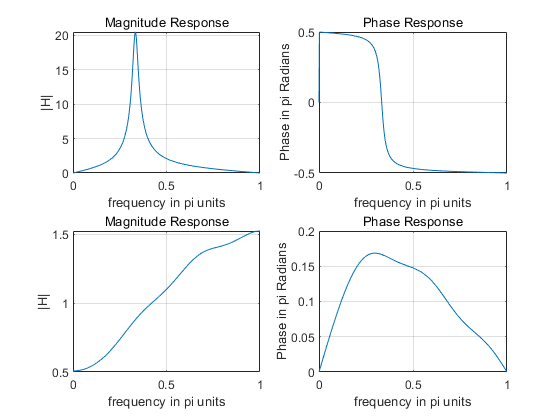

b = [1];
a = [1 0.5 0.5^2 0.5^3 0.5^4 0.5^5];

m = 0:length(b)-1; l = 0:length(a)-1;

K = 500; k = 0:1:K;

w = pi*k/K;
num = b* exp(-j*m'*w);
den = a* exp(-j*l'*w);
H = num ./ den;

magH = abs(H);
angH = angle(H);
subplot(2,2,3); plot(w/pi, magH); 
xlabel('frequency in pi units'); ylabel('|H|'); grid;
title('Magnitude Response');
subplot(2,2,4); plot(w/pi, angH/pi);
xlabel('frequency in pi units'); ylabel('Phase in pi Radians'); grid;
title('Phase Response');

function [H] = freqresp(b,a,w)
% H = frequency response array evaluated at w frequencies
% b = numerator coefficient array
% a = denominator coefficient array (a(1) = 1)
% w = frequency location array


b= rand(1,10);

c = rand(1,8);
a= [0 1, c];
m = 0:length(b)-1; l = 1:length(a)-1;

K = 500; k = 0:1:K;

w = pi*k/K;

end

